**Existence of global optima for quadratic programming problems**

Prove that the quadratic programming problem has a global optimum.


$$\left\lbrace \begin{array}{ll}
\mathrm{minimize} & \frac{1}{2}x_1^2 -x_2^2 +x_1 -{2x}_2 \\
\mathrm{subject}\;\mathrm{to} & {-x}_1 {+x}_2 \le -1\\
\; & {-x}_2 \le 0
\end{array}\right.$$


close all;
clear;
clc;

matlab.lang.OnOffSwitchState = 1;

Q = [1 0
     0 -1];


% The Quadratic Problem is indefinite
eig(Q)

ans =     -1
     1


% Objective function
f = @(x1,x2) (1/2).*x1.^2 - (1/2).*x2.^2 + x1 - 2.*x2;
g1 = @(x1,x2) -x1 + x2 <= -1;
g2 = @(x1,x2) -x2 <= 0;

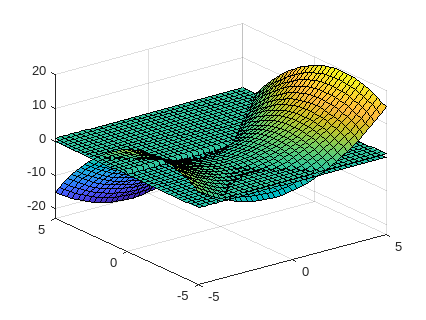

% 3D Surface plot

fsurf(f);
hold on
fsurf(g1);
fsurf(g2);
hold off

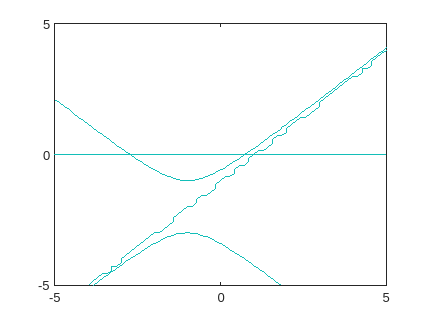

% 2D Contour plot 

fcontour(f, 'LevelList',1);
hold on
fcontour(g1,'LevelList',1);
fcontour(g2, 'LevelList',1);
hold off